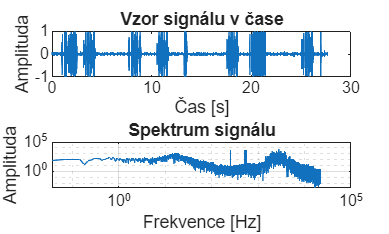

clear all; close all; clc;

% 1. Načtení souboru
[signal, Fs] = audioread('data\264012.wav'); % Doplňte vaše ID souboru
N = length(signal);              % Délka signálu
t = (0:N-1) / Fs;                % Časová osa

% 2. Výpočet spektra (FFT)
Y = fft(signal);                 % Fourierova transformace
f = (0:N-1) * (Fs / N);          % Frekvenční osa

% 3. Vykreslení (Bod 1 zadání)
figure(1);
subplot(2,1,1);
plot(t, signal);
title('Vzor signálu v čase');
xlabel('Čas [s]'); ylabel('Amplituda');

subplot(2,1,2);
% Zobrazíme jen polovinu spektra (do Fs/2), protože je symetrické
% a použijeme abs(Y) pro velikost (modul) spektra
loglog(f(1:floor(N/2)), abs(Y(1:floor(N/2)))); 
title('Spektrum signálu');
xlabel('Frekvence [Hz]'); ylabel('Amplituda');
grid on;





limit=150

limit = 150

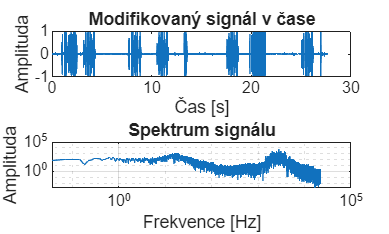

for k = 2:N-1
    if abs(Y(k)) > limit * abs(Y(k-1))
        if abs(Y(k)) > limit * abs(Y(k+1))
            Y(k) = 0; % Nullify the member if it is 150 times larger than the preceding member
        end
    end
end

% 4. Inverse FFT to reconstruct the modified signal
modifiedSignal = ifft(Y, 'symmetric');

% 5. Vykreslení modifikovaného signálu
figure(2);
subplot(2,1,1);
plot(t, modifiedSignal);
title('Modifikovaný signál v čase');
xlabel('Čas [s]'); ylabel('Amplituda');

subplot(2,1,2);
% Zobrazíme jen polovinu spektra (do Fs/2), protože je symetrické
% a použijeme abs(Y) pro velikost (modul) spektra
loglog(f(1:floor(N/2)), abs(Y(1:floor(N/2)))); 
title('Spektrum signálu');
xlabel('Frekvence [Hz]'); ylabel('Amplituda');
grid on;



audiowrite("data\out.wav",modifiedSignal,Fs)